  259.4397

   263

     6.218755097122578e-04



     2.505706427219263e+02

   300

     7.604687622608082e-04



     2.331944192342873e+02

   159

     4.653517133810771e-04



     2.175952353935149e+02

   177

     5.949699092917423e-04



     1.578802220944264e+02

   195

   0.001245086867724



     1.613527995119430e+02

   385

   0.002353575953053



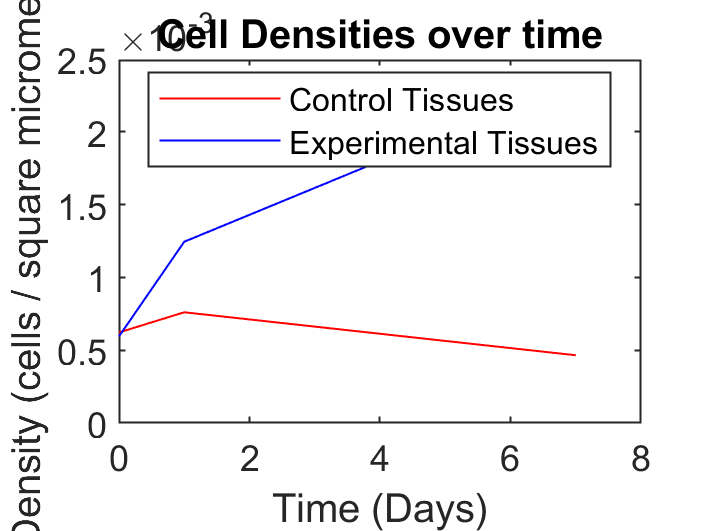

Elapsed time is 2.882816 seconds.


cont 0 to 1


     1.385932525485504e-04



exper 0 to 1


     6.501169584320959e-04



cont 1 to 7


     7.604687622608082e-04



     4.653517133810771e-04



    -4.918617481328852e-05



exper 1 to 7


     1.847481808882168e-04



% Cameron McNamee 8-31-2022 McLaughlin Research Institute
% Determine the clustering of the image
% This data can be compared between images to then develop a 
% "clustering velocity" that can be compared between the control
% and the experimental samples
clear

% Loading image
img = imread('example.png');


% Pass image through function
rho = image2cd(img, 4);


function rho = image2cd(img, d)
    % Convert image to grayscale
    img_gray = rgb2gray(img);
    img_binary = imbinarize(img_gray, 0.1);

    % Opening and closing by reconstruction
    se = strel('disk', 5);
    img_erode = imerode(img_binary, se);
    img_open = imreconstruct(img_erode, img_binary);
    img_dilate = imdilate(img_open, se);
    img_noise_removed = imreconstruct(imcomplement(img_dilate), ...
                        imcomplement(img_open));
    img_noise_removed = imcomplement(img_noise_removed);

    % Watershed Segmentation
    D = bwdist(~img_noise_removed);
    L = watershed(-D);
    L(~img_noise_removed) = 0;

    % Identifying centroids
    cents = regionprops(L, 'Centroid');
    centroids = cat(1, cents.Centroid);
    num_cells = size(centroids(:, 1));
    num_cells = num_cells(1);

    % Calculating radial distribution
    distances = centerDistance(centroids);
    [N, tempedges] = histcounts(distances, ...
        'Normalization', 'cdf', 'BinWidth', 5);
    edges = tempedges(2:end) - (tempedges(2)-tempedges(1))/2;
    
    % Inserting (0, 0) at the beginning
    N = [0 N(1:end)];
    edges = [0, edges(1:end)];
  
    % Fitting
    p = polyfit(edges, N, d);

    % R50
    p(d+1) = p(d+1) - 0.5;
    r = roots(p);
    r = r(imag(r) == 0);
    r = r(real(r) > 0);
    r50 = min(r);
    r50 = r50 * 0.8333; % constant given from ratio of 120px = 100 micrometers
    disp(r50);
    disp(num_cells);

    % Calculating cell density
    rho = (num_cells * 0.5) / (3.14159 * (r50)^2);
end

function distances = centerDistance(cent)
    xCentroid = mean(cent(:, 1));
    yCentroid = mean(cent(:, 2));
    distances = sort(sqrt((xCentroid-cent(:,1)).^2+(yCentroid-cent(:,2)).^2));
end